clc
clear
%discrete time system
% E x[n + 1] = Ax[n] + Bu[n] + Gw[n] (in the example B = G)
%     y[n] = Cx[n] + Du[n] + Hw[n] + v[n]

Fc = 60; %frequency 60Hz
Av =1;  % amplitude
Ts = 0.0005; % 1/0.0005 = 2 kHz  campionamento
omega = 2*pi*Fc; % angular frequency constant over time
StopTime = 0.1;             % seconds
t = (0:Ts:0.0005)';     % seconds
% Set up plant model:

%============= Model is at steady state ===========
A =  [1 0; 0 1];
B =  [0;0];
C =  [cos(omega*t), -sin(omega*t)];  % frequenza di 60Hz
D = 0;
E = eye(2);

plant = dss(A, B, C, D, E); 

Q = eye(2); %process_noise_cov
R =  1; %sensor_noise_cov
W = eye(2);
U = 1;

n = 2;
m = 2;
P = [0 0;0 0];
S = 0;

%   [KEST,L,P] = KALMAN(SYS,QN,RN,NN) designs a Kalman estimator KEST for
%   the continuous- or discrete-time plant SYS. For continuous-time plants
%   QN = E{ww'} = I,     RN = E{vv'} = I,     NN = E{wv'} = 0 se uncorrelated.
% 
%   [KEST,L,P,Mx,Z,My] = KALMAN(SYS,QN,RN,...,TYPE) specifies the estimator
%   type for discrete-time plants SYS. The string TYPE is either 'current'
%   (default) or 'delayed'. KALMAN returns the estimator and innovation 
%   gains L,Mx,My and the steady-state error covariances:
%       P = E{(x - x[n|n-1])(x - x[n|n-1])'}   (Riccati solution)
%       Z = E{(x - x[n|n])(x - x[n|n])'}
 
% [KEST,L,P,Mx,Z,My] = kalman(plant, Q, R, 0);

% n = size(A,1);
% m = size(B,2);
% p = size(C,1);
% R = blkdiag(eye(m),-eye(p));
% BB = [B,zeros(n,p)];
% S = [zeros(n,m),C'];
% %Here, X2 is the unique stabilizing solution, K2 contains the state-feedback gain and L2 contains the closed-loop eigenvalues.
% [X2,K2,L2,info] = icare(A,BB,0,R,S,[],[])

% kalman filter
% P = A*P*A' + Q - A*P*C'*inv(C*P*C' + R)*C*P*A'


% K = A*P*C'*inv(C*P*C'+R);
[P,~,~] = dare(A',C',Q, R);
[S,~,L] = idare(A,B,W,U);
L = -L;
K = A*P*C'*inv(C*P*C'+R);

cP = C*P*C' + R;
invcP = inv(cP);

Gamma = diag([0,1])

Gamma =      0     0
     0     1


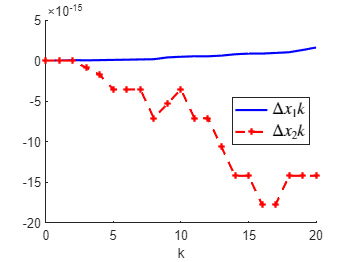


% v is an unstable eigenvector for A
% the corresponding eigenvalue is 1
% Cv is in the span of Gamma
v = [0;1];
lambda = 1;

% calculate the attacker's input to reach v
Co = -[(A-K*C*A)*K*Gamma K*Gamma];

ya = Co\v;
% reshape ya from [ya(0);ya(1)] to [ya(0),ya(1)]
ya = reshape(ya,m,[]);

e(:,1) = -K*Gamma*ya(:,1);

z(:,1) = Gamma*ya(:,1);

e(:,2) = (A-K*C*A)*e(:,1)-K*Gamma*ya(:,2);
z(:,2) = C*A*e(:,1) + Gamma*ya(:,2);

M = max(norm(z(:,1)),norm(z(:,2)));

ya = ya/M;

%easy to verify that Gamma ystar = Cv
ystar = C*v;


for i = 3:31
    ya(:,i) = ya(:,i-2) - lambda^(i-2)/M*ystar;
end

e(:,1) = -K*Gamma*ya(:,1);
z(:,1) = Gamma*ya(:,1);
for i=2:21
    e(:,i) = (A-K*C*A) * e(:,i-1) - K*Gamma * ya(:,i);
    z(:,i) = C*A * e(:,i-1) + Gamma * ya(:,i);
end

% ya =-ya;

for i = 1:21
    normz(i) = norm(z(:,i));
end

hatx(:,1) = K*z(:,1);

for i = 2:21
    hatx(:,i) = A*hatx(:,i-1)+K*z(:,i);
end
x = hatx + e;

figure(1)
hold on
plot(0:20,x(1,:),'b-','Linewidth',2);
plot(0:20,x(2,:),'r+--','Linewidth',2);
legend('$\Delta x_1k$', '$\Delta x_2k$','location','best');
h = legend;
set(h, 'interpreter', 'latex','fontsize',16)
xlabel('k','fontsize',12);
h = gca;
set(h,'Fontsize',12);
hold off

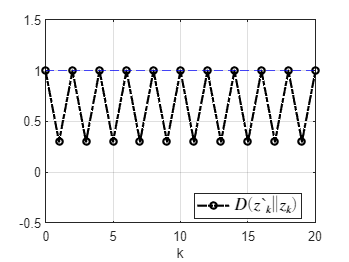


figure(2)
plot(0:20,normz,'ko-.','Linewidth',2);
yline(1,'--b'); grid on;
ylim([-0.5,1.5]);
legend('$D(z`_k\|z_k)$','location','best');
h = legend;
set(h, 'interpreter', 'latex','fontsize',16)
xlabel('k','fontsize',12);
h = gca;
set(h,'Fontsize',12);

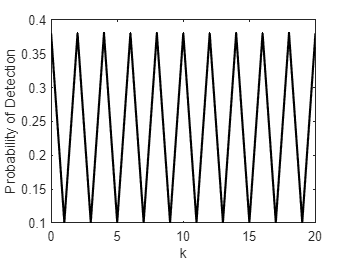




thre = chi2inv(0.95,m);
for i = 1:21
    %g_k follow a non-central chi^2 distribution
    detectionprob(i) = 1 - ncx2cdf(thre, m, z(:,i)'*invcP*z(:,i));
end

figure(3)
plot(0:20,detectionprob,'k','Linewidth',2);
xlabel('k','fontsize',12);
ylabel('Probability of Detection','fontsize',12);
h = gca;
set(h,'Fontsize',12);